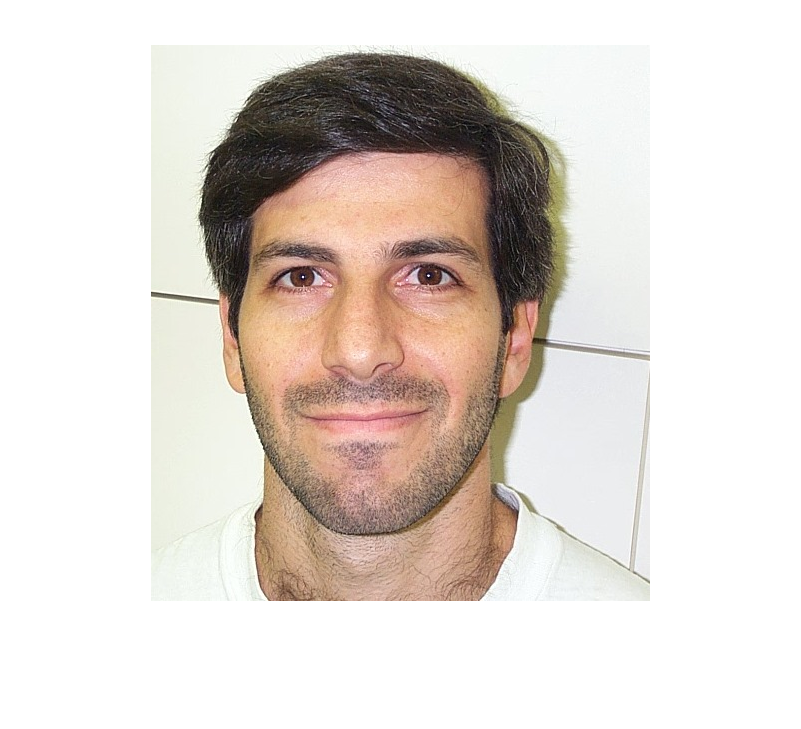

clear
img = (imread("a.png"));
images = loadFiles(dir("DB1/*.jpg"));

m = [110.3, 142.5];
C = [130.16, 10.15; 11.07, 280.35];

image = cell2mat(images(1,9));
imshow(image);

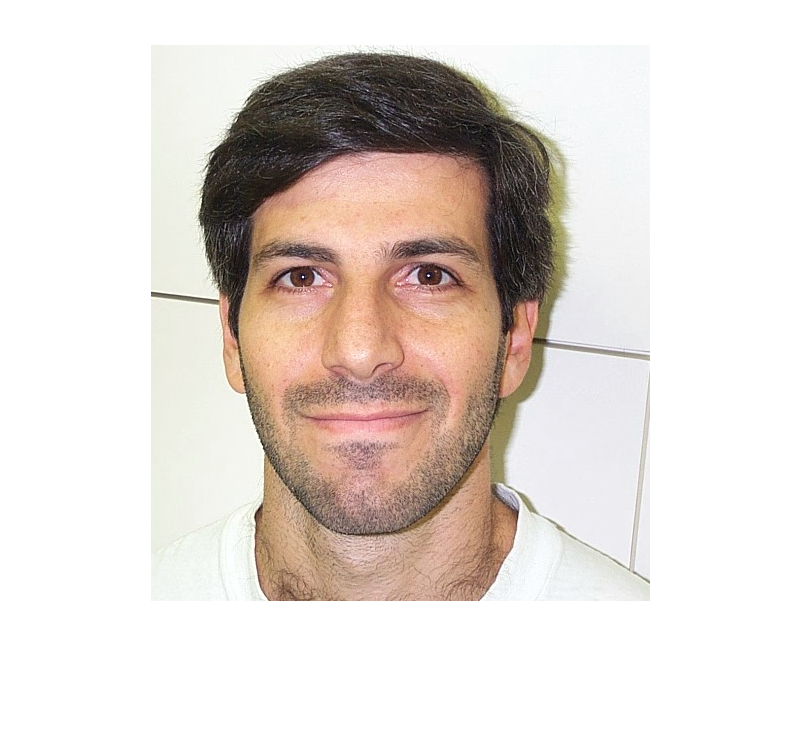


imageW = whitePoint(image);
imshow(imageW);

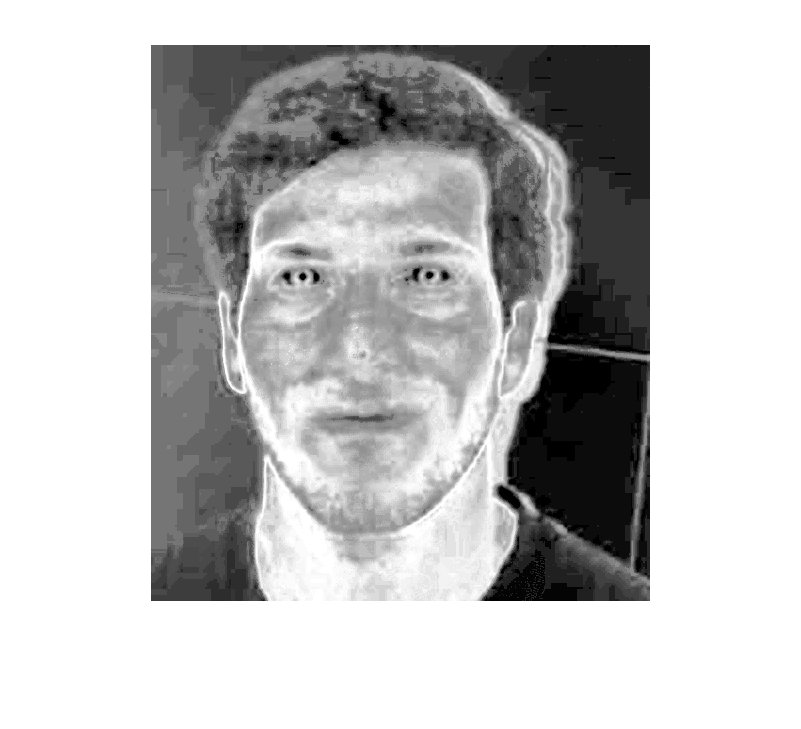


imageG =(gaussian(imageW, m, C));
imshow(imageG);

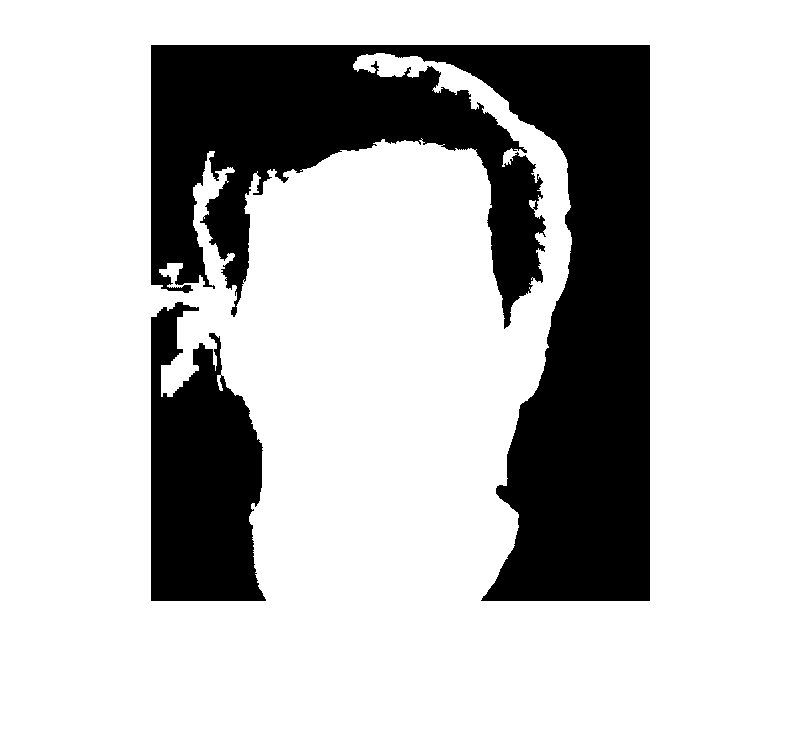


mask = skinMask(imageG);

imshow(mask);

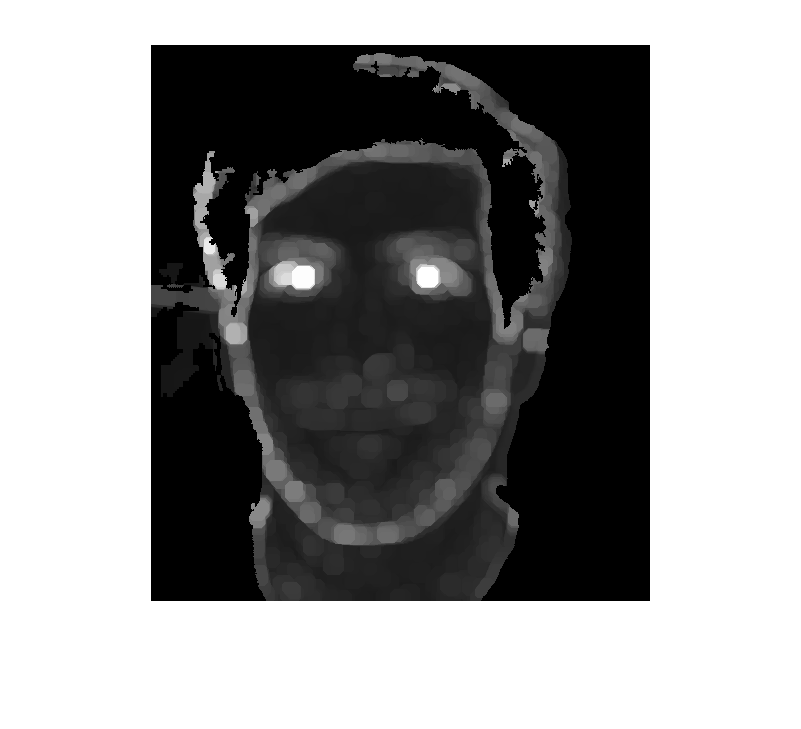


eyeMapped = eyemap(imageW, mask);
imshow(eyeMapped);


eyes = findEyes(eyeMapped);

stats =    82.5000  289.5000    1.0595
  277.2000  231.5420    1.0479
  144.4163  231.2098    0.8628
   68.9071  234.9867    0.7333
   58.9578  202.3434    0.6406
   55.6788  138.9051    0.6353


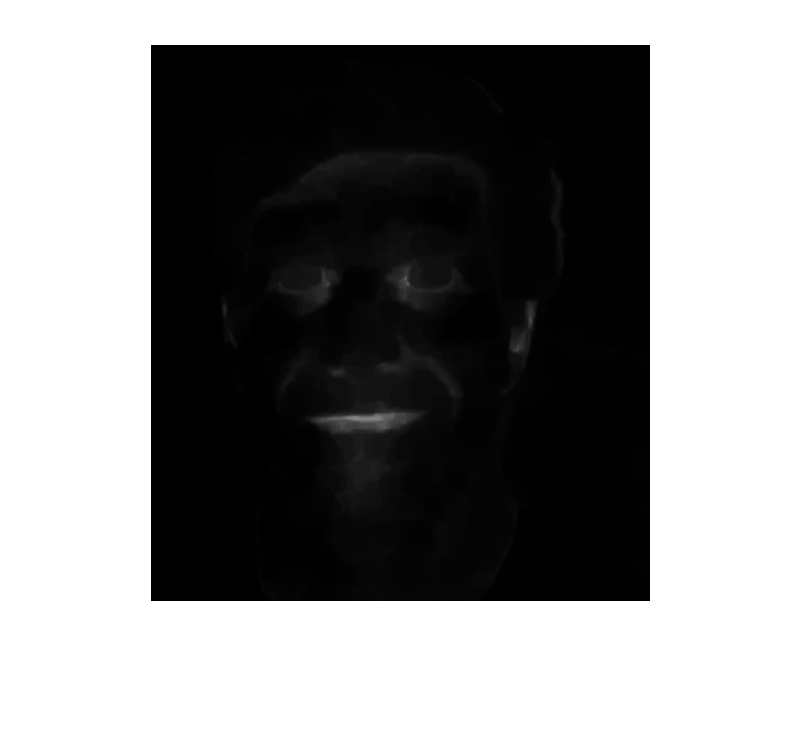


mouthMapped = mouthmap(image);
imshow(mouthMapped)

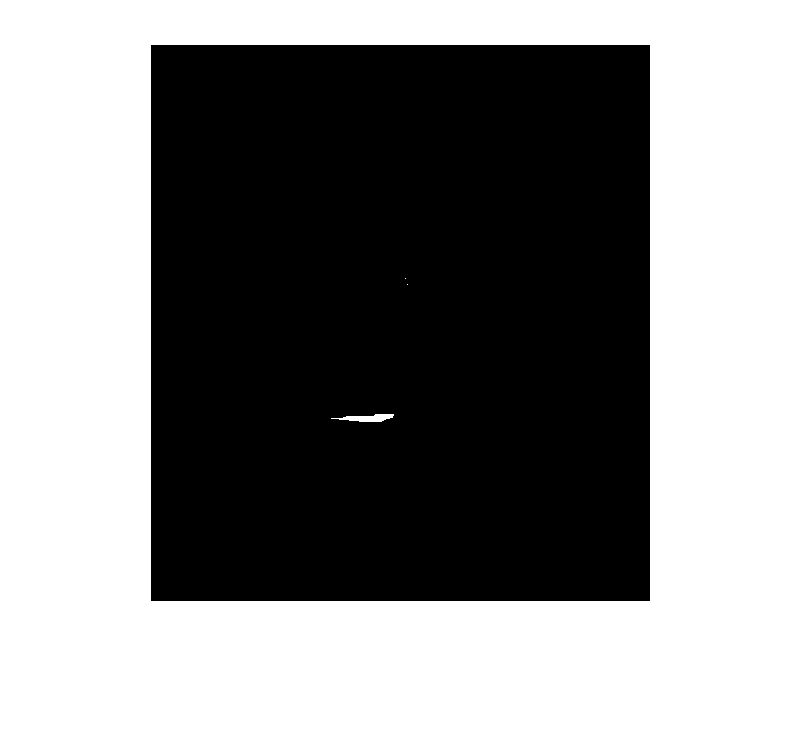

stats = 3×1 struct array with fields:
    Centroid



mouth = findMouth(mouthMapped);

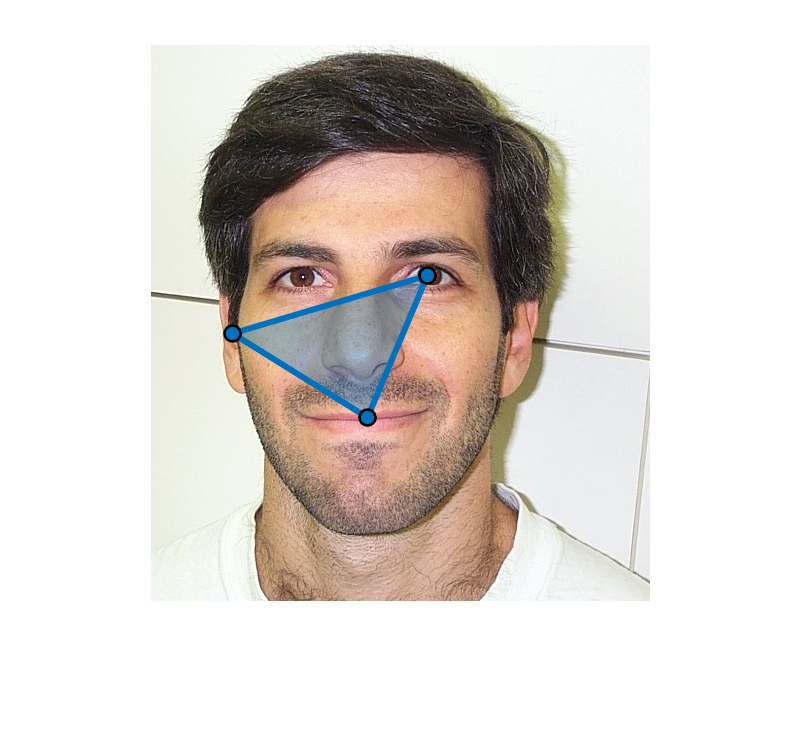


triangle = drawTriangle(eyes, mouth, image);